# WHY THE PSEUDOINVERSE FAILS FOR ILL-POSED PROBLEMS

clear; clc; close all;

#### 1. Load Full Image

image_path = '296059.jpg';  
img = imread(image_path);

% Convert to grayscale 
if ndims(img) == 3
    img = mean(double(img), 3);
else
    img = double(img);
end

% Normalize
x_full = img / max(img(:));

fprintf('Full image shape: %d x %d\n', size(x_full, 1), size(x_full, 2));

Full image shape: 321 x 481


#### 2. Gaussian Blur Kernel (Forward Operator)

kernel_size = 9;
sigma = 2.0;

half_size = floor(kernel_size / 2);
[xx, yy] = meshgrid(-half_size:half_size, -half_size:half_size);
kernel = exp(-(xx.^2 + yy.^2) / (2 * sigma^2));
kernel = kernel / sum(kernel(:));

#### 3. Extract a 16x16 PATCH 

patch = x_full(101:116, 101:116);
patch = patch / max(patch(:));

n = size(patch, 1);
assert(all(size(patch) == [16, 16]), 'Patch must be 16x16');

#### 4. Build Convolution Matrix A 

N = n * n;  % 256
A = zeros(N, N);

for i = 1:N
    % Create basis image with single 1 at position i
    basis = zeros(n, n);
    basis(i) = 1.0;
    
    % Apply convolution with symmetric boundary
    conv_result = imfilter(basis, kernel, 'symmetric', 'same');
    
    % Store as column of A
    A(:, i) = conv_result(:);
end

fprintf('Explicit A shape: %d x %d\n', size(A, 1), size(A, 2));

Explicit A shape: 256 x 256


#### 5. Forward Model on Patch: y = A*x + epsilon

Ax_patch = imfilter(patch, kernel, 'symmetric', 'same');

noise_std = 0.01;
eps = noise_std * randn(size(Ax_patch));
y_patch = Ax_patch + eps;

x_vec = patch(:);
y_vec = y_patch(:);

#### 6. Singular Value Decomposition of A-

[U, S_mat, V] = svd(A, 'econ');
S = diag(S_mat);  % Extract singular values as vector

condition_number = S(1) / S(end);
fprintf('Condition number of A: %.2e\n', condition_number);

Condition number of A: 5.87e+07


#### 7. Moore-Penrose Pseudoinverse Reconstruction

S_inv = diag(1.0 ./ S);
x_pinv = V * S_inv * U' * y_vec;
x_pinv_img = reshape(x_pinv, [n, n]);

#### 8. Visual Comparison

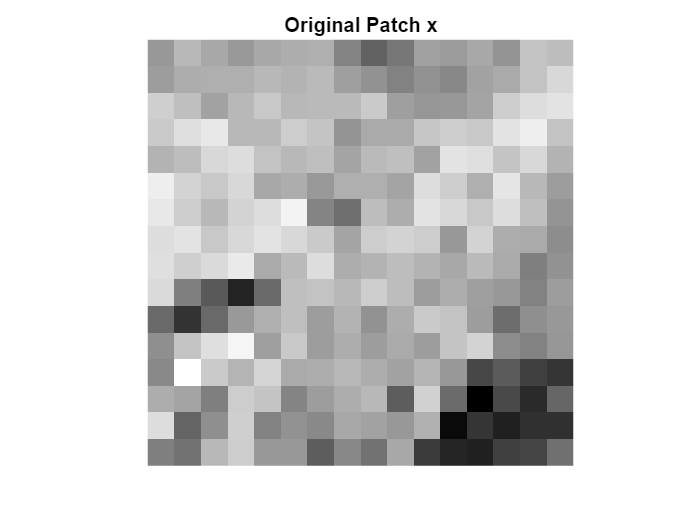

imagesc(patch);
colormap gray;
axis image off;
title('Original Patch x');

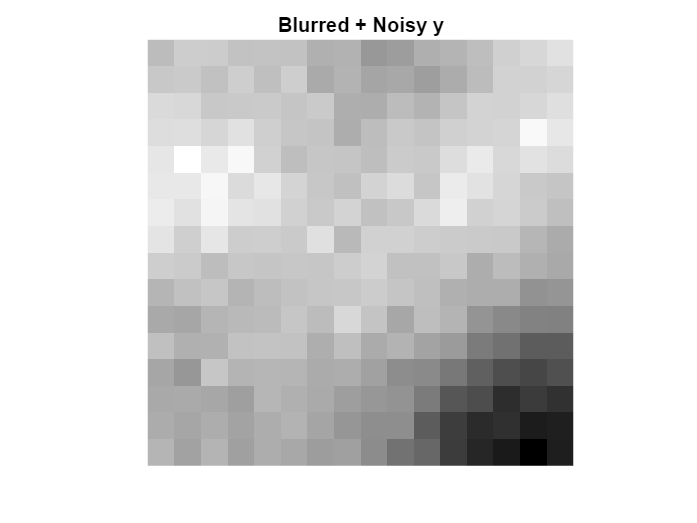



imagesc(y_patch);
colormap gray;
axis image off;
title('Blurred + Noisy y');

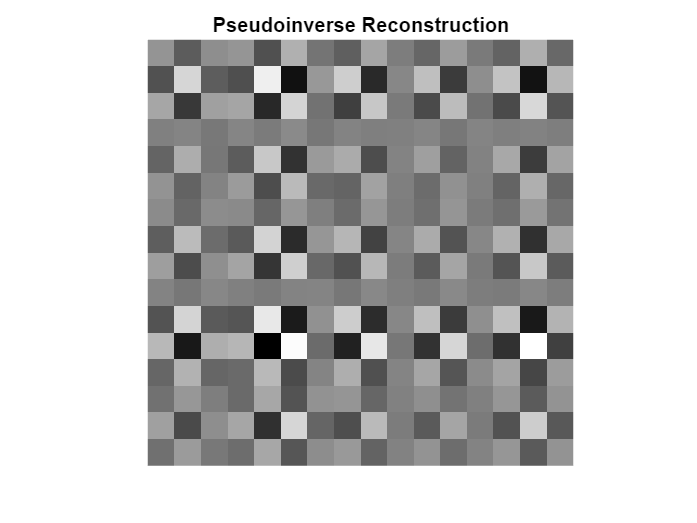



imagesc(x_pinv_img);
colormap gray;
axis image off;
title('Pseudoinverse Reconstruction');

#### 9. Singular Value Decay (Root Cause)

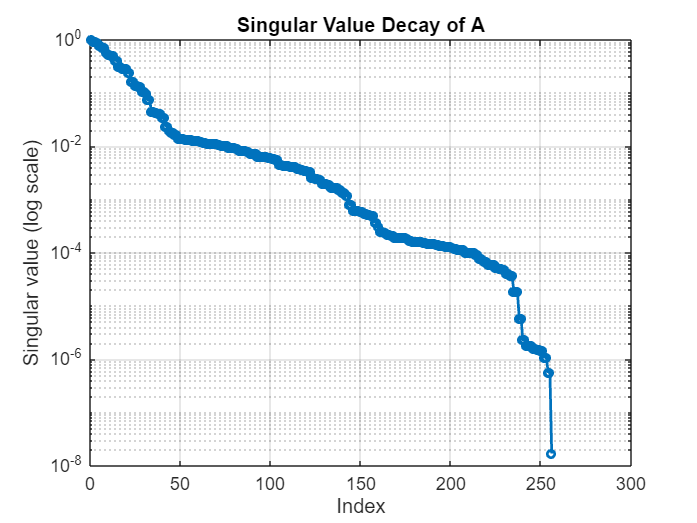

figure;
semilogy(S, 'o-', 'LineWidth', 1.5, 'MarkerSize', 4);
xlabel('Index');
ylabel('Singular value (log scale)');
title('Singular Value Decay of A');
grid on;

#### 10. Quantitative Instability Evidence

rel_error = norm(x_pinv_img(:) - patch(:)) / norm(patch(:));
fprintf('Relative reconstruction error (pseudoinverse): %.4f\n', rel_error);

Relative reconstruction error (pseudoinverse): 8876.9628


fprintf('\n*** Pseudoinverse amplifies noise due to small singular values! ***\n');


*** Pseudoinverse amplifies noise due to small singular values! ***
